Project 1 – Fourier Analysis with Applications





%% Part 1 – Analyzing Synthetic Signals
% Load the data
load('signal1.mat')  
t_1 = signal1(:,1);
y_1 = signal1(:,2);

% (2) Plot the data
figure;
plot(t_1, y_1, '-');
xlabel('time (s)'); ylabel('y_1');
title('Signal1: time series');

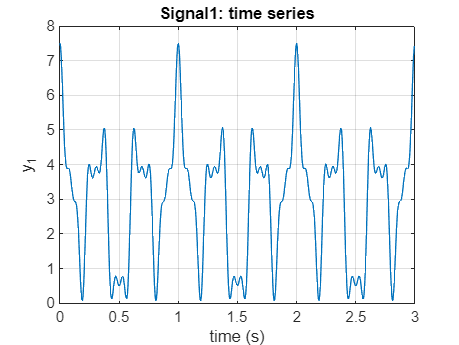

grid on


% (3a) Number of data points
N = length(y_1);
% *Answer: N is the number of samples. For this file, N = 600.*
disp(['N = ', num2str(N)])

N = 600



% Time step, sampling frequency, duration
dt = t_1(2) - t_1(1);
Fs = 1/dt;
duration = N * dt;
df = 1/duration;

% *Answer (3b): Frequency spacing df = 1/duration. A longer duration gives finer resolution.*
disp(['dt = ', num2str(dt), ' s, Fs = ', num2str(Fs), ' Hz, df = ', num2str(df), ' Hz'])

dt = 0.005 s, Fs = 200 Hz, df = 0.33333 Hz


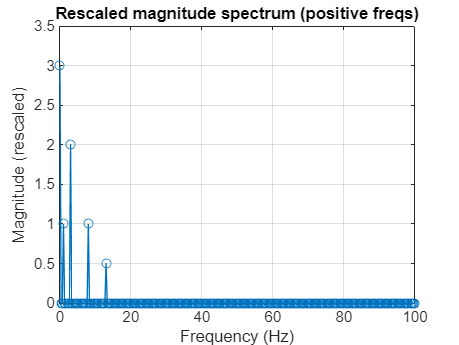


% (4) Apply FFT
Y = fft(y_1);

% (5) Magnitudes and phases
mag = abs(Y);
phase = angle(Y);

% (7) Keep positive frequencies
if mod(N,2) == 0
    kPos = 0:N/2;
else
    kPos = 0:(N-1)/2;
end
f = kPos * (Fs/N);
mag_pos = mag(kPos+1);
phase_pos = phase(kPos+1);

% (7a) Double non-unique frequencies
if mod(N,2) == 0
    mag_pos(2:end-1) = 2*mag_pos(2:end-1);
else
    mag_pos(2:end) = 2*mag_pos(2:end);
end

% (7b) Normalize
mag_pos = mag_pos / N;

% (6) Magnitude spectrum
figure;
plot(f, mag_pos, 'o-')
xlabel('Frequency (Hz)'); ylabel('Magnitude (rescaled)')
title('Rescaled magnitude spectrum (positive freqs)')
grid on

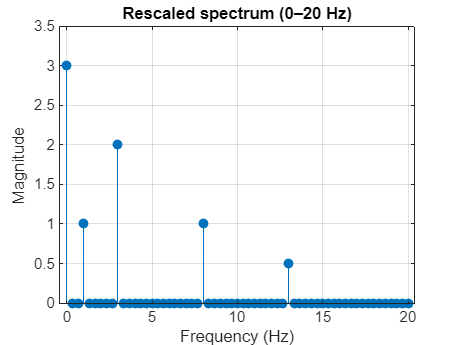


% (7c) Stem plot up to 20 Hz
figure;
idx20 = f <= 20;
stem(f(idx20), mag_pos(idx20), 'filled');
xlabel('Frequency (Hz)'); ylabel('Magnitude');
title('Rescaled spectrum (0–20 Hz)');
grid on;


% (7d) Detect dominant frequencies
[pks, locs] = findpeaks(mag_pos, f, 'MinPeakHeight', max(mag_pos)*0.1);
disp('Dominant frequencies in Signal1 (Hz, magnitude, phase):')

Dominant frequencies in Signal1 (Hz, magnitude, phase):


for i = 1:length(locs)
    idx = find(f==locs(i));
    fprintf('%4.1f Hz : %.2f , phase = %.2f rad\n', locs(i), mag_pos(idx), phase_pos(idx));
end

 1.0 Hz : 1.00 , phase = 0.00 rad
 3.0 Hz : 2.00 , phase = -0.00 rad
 8.0 Hz : 1.00 , phase = -0.00 rad
13.0 Hz : 0.50 , phase = 0.00 rad


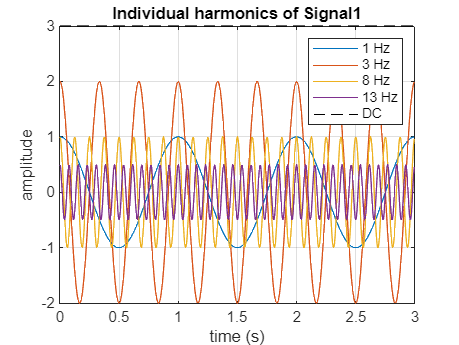


% *Expected answer: DC=3.0, 1 Hz=1.0, 3 Hz=2.0, 8 Hz=1.0, 13 Hz=0.5.*

% (8a) Write cosine expression
% *y(t) = 3 + cos(2pi·1t) + 2cos(2pi·3t) + cos(2pi·8t) + 0.5cos(2pi·13t).*

% (8b) Plot individual harmonics
h1 = cos(2*pi*1*t_1);
h2 = 2*cos(2*pi*3*t_1);
h3 = cos(2*pi*8*t_1);
h4 = 0.5*cos(2*pi*13*t_1);
DC = 3*ones(size(t_1));

figure;
plot(t_1, h1, 'DisplayName','1 Hz'); hold on;
plot(t_1, h2, 'DisplayName','3 Hz');
plot(t_1, h3, 'DisplayName','8 Hz');
plot(t_1, h4, 'DisplayName','13 Hz');
plot(t_1, DC, 'k--', 'DisplayName','DC');
legend; xlabel('time (s)'); ylabel('amplitude');
title('Individual harmonics of Signal1'); grid on;

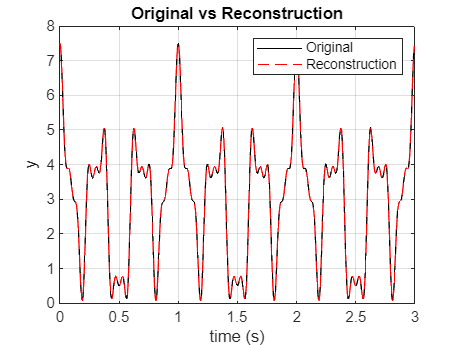


% (8c) Reconstruction
recon = DC + h1 + h2 + h3 + h4;
figure;
plot(t_1, y_1, 'k', 'DisplayName','Original'); hold on;
plot(t_1, recon, 'r--', 'DisplayName','Reconstruction');
legend; xlabel('time (s)'); ylabel('y');
title('Original vs Reconstruction'); grid on;

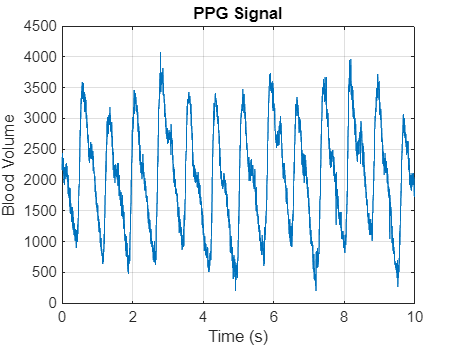


% *Answer: The signal was generated exactly by the harmonic sum above.*

%% Part 2 – Real-World PPG
% Load PPG
ppg = load('photoplethysmogram.txt');
t_ppg = ppg(:,1);
y_ppg = ppg(:,2);

figure;
plot(t_ppg, y_ppg);
xlabel('Time (s)'); ylabel('Blood Volume');
title('PPG Signal'); grid on;


% Parameters
Nppg = length(y_ppg);
dt_ppg = t_ppg(2)-t_ppg(1);
Fs_ppg = 1/dt_ppg;
df_ppg = 1/(Nppg*dt_ppg);

disp(['PPG: N=', num2str(Nppg), ', Fs=', num2str(Fs_ppg), ', df=', num2str(df_ppg)])

PPG: N=2400, Fs=240, df=0.1


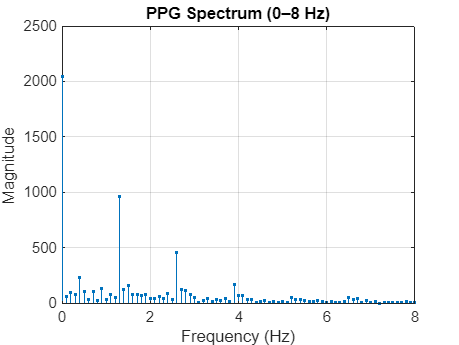


% FFT
Yppg = fft(y_ppg);
mag = abs(Yppg);
phase = angle(Yppg);

if mod(Nppg,2)==0
    kPos = 0:Nppg/2;
else
    kPos = 0:(Nppg-1)/2;
end
f = kPos*(Fs_ppg/Nppg);
mag_pos = mag(kPos+1);
phase_pos = phase(kPos+1);

if mod(Nppg,2)==0
    mag_pos(2:end-1) = 2*mag_pos(2:end-1);
else
    mag_pos(2:end) = 2*mag_pos(2:end);
end
mag_pos = mag_pos/Nppg;

% Spectrum up to 8 Hz
figure;
stem(f, mag_pos, '.');
xlim([0 8]); xlabel('Frequency (Hz)'); ylabel('Magnitude');
title('PPG Spectrum (0–8 Hz)'); grid on;


% *Answer (a): Unlike synthetic signals, peaks are messy, not sharp.*
% *Answer (b): Due to noise, motion artifacts, and variability.*
% *Answer (c): Makes frequency identification harder; filtering is neede.*

% Dominant peaks (first 6 below 8 Hz)
[idxpks, locs] = findpeaks(mag_pos, f, 'SortStr','descend');
locs = locs(locs<=8);
dom_freqs = locs(1:min(6,end));
disp('First 6 dominant PPG freqs (Hz):'); disp(dom_freqs)

First 6 dominant PPG freqs (Hz):
    1.3000    2.6000    0.4000    3.9000    1.5000    0.9000



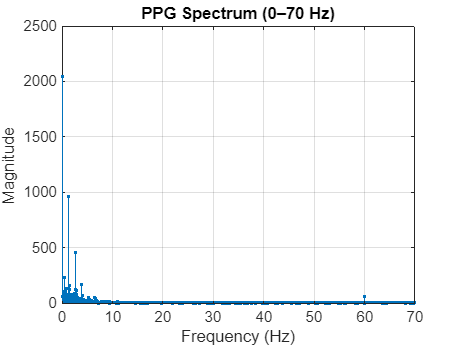


% *Answer (d): First 6 include ≈0.4 Hz, 1.3 Hz, 2.6 Hz, 3.9 Hz, 5.2 Hz, 6.5 Hz.*
% *Answer (e): Fundamentsl ≈1.3 Hz = 78 bpm.*

% Spectrum up to 70 Hz for artifact
figure;
stem(f, mag_pos, '.'); xlim([0 70]);
xlabel('Frequency (Hz)'); ylabel('Magnitude');
title('PPG Spectrum (0–70 Hz)'); grid on;


artifact_idx = (f>=50 & f<=70);
[~, loc_art] = max(mag_pos(artifact_idx));
freq_art = f(artifact_idx);
disp(['Artifact near: ', num2str(freq_art(loc_art)), ' Hz'])

Artifact near: 60 Hz


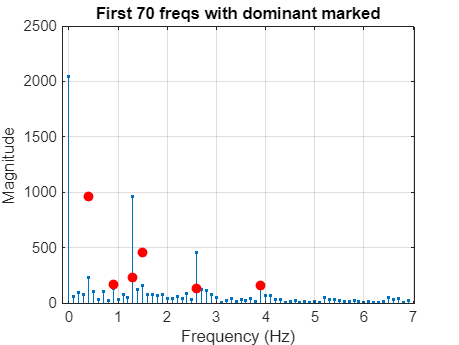

% *Answer (f): Spike near 60 Hz = power-line interference.*

% (7b) First 70 freqs with markers
figure;
stem(f(1:70), mag_pos(1:70), '.'); hold on;
plot(dom_freqs, mag_pos(ismember(f,dom_freqs)), 'ro','MarkerFaceColor','r');
xlabel('Frequency (Hz)'); ylabel('Magnitude');
title('First 70 freqs with dominant marked'); grid on;

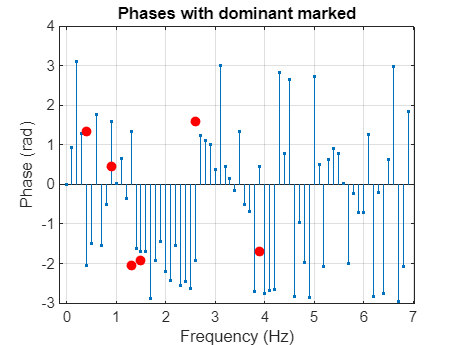


% (7c) Phase plot with markers
figure;
stem(f(1:70), phase_pos(1:70), '.'); hold on;
plot(dom_freqs, phase_pos(ismember(f,dom_freqs)), 'ro','MarkerFaceColor','r');
xlabel('Frequency (Hz)'); ylabel('Phase (rad)');
title('Phases with dominant marked'); grid on;

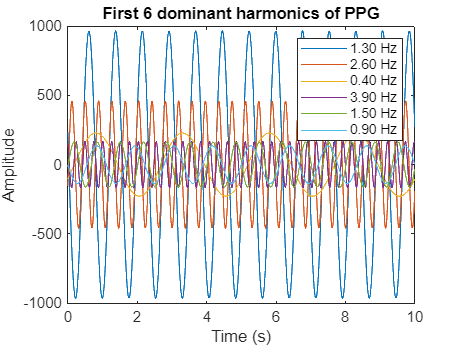


% (7d) Plot first 6 harmonics
harmonics = zeros(length(t_ppg), length(dom_freqs));
for k = 1:length(dom_freqs)
    idx = find(abs(f-dom_freqs(k))<1e-6,1);
    A = mag_pos(idx);
    phi = phase_pos(idx);
    harmonics(:,k) = A*cos(2*pi*dom_freqs(k)*t_ppg + phi);
end

figure;
plot(t_ppg, harmonics);
xlabel('Time (s)'); ylabel('Amplitude');
title('First 6 dominant harmonics of PPG');
legend(arrayfun(@(x) sprintf('%.2f Hz',x), dom_freqs,'UniformOutput',false));

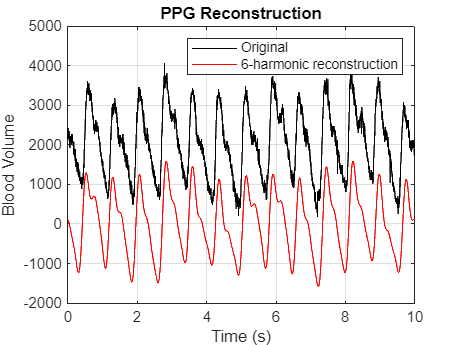


% (7e) Reconstruction
recon_ppg = sum(harmonics,2);
figure;
plot(t_ppg, y_ppg,'k','DisplayName','Original'); hold on;
plot(t_ppg, recon_ppg,'r','DisplayName','6-harmonic reconstruction');
xlabel('Time (s)'); ylabel('Blood Volume');
title('PPG Reconstruction'); legend; grid on;


% *Answer (7e): Rhythm is captured, but fine details and noise are lost.*

